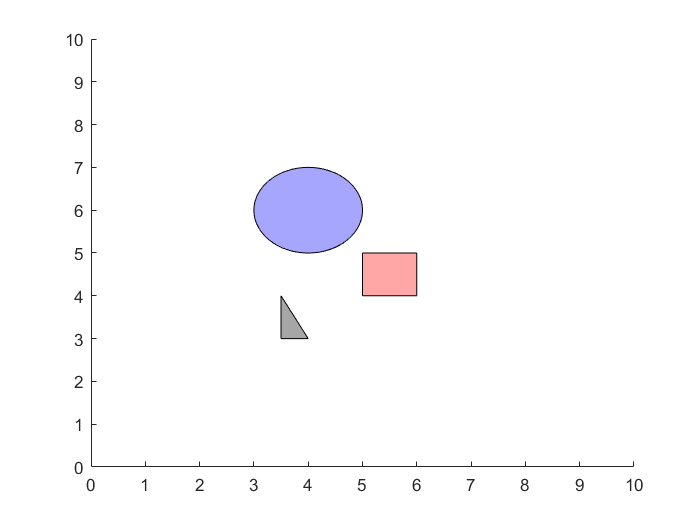

%Samarth Sachan
%190749

clc;
close all
clear all
f1 = figure;


p1 = polyshape([5 5 6 6],[4 5 5 4]);
p3 = polyshape([3.5 4;4 3;3.5 3]);

figure(f1)
axis([0 10 0 10]);
hold on

%plotting circle
p2 = nsidedpoly(1000, 'Center', [4 6], 'Radius', 1);
plot(p2, 'FaceColor', 'blue');

plot (p1,'FaceColor','red'); % square

plot(p3,'FaceColor','black'); % traingle

% local repulsive field for objects

zone1.R = 1;  % for square
zone1.center = [5.5;4.5];


zone2.R = 1.5;   % for blue circe
zone2.center = [4;6];

zone3.R = 1;   % for traingle
zone3.center = [3.75;3.5];


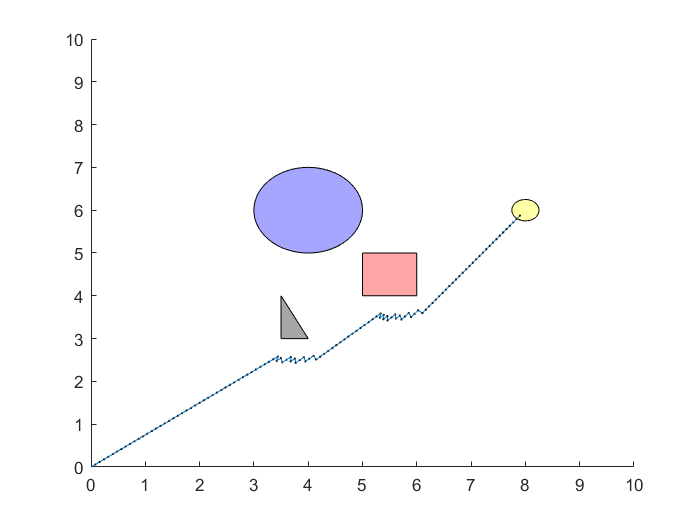


cpoint = [0;0]; % current point (starting point)
gpoint = [8;6]; % goal point marked with a yellow circle


gzone.R = 0.25; % zone area of goal
gzone.center = gpoint;
p4 = nsidedpoly(1000, 'Center', [gpoint(1) gpoint(2)], 'Radius', gzone.R);
plot(p4, 'FaceColor', 'yellow');


stepSize = 0.1;
for i= 1:500
    direction = force(cpoint,gpoint,zone1,zone2,zone3);
    new_point = cpoint + stepSize*direction;
    figure(f1)
    line([cpoint(1),new_point(1)],[cpoint(2),new_point(2)]);
    hold on
    scatter(new_point(1),new_point(2),1,'black')
    cpoint = new_point;
    
    if gzone.R > calcDistance(gzone.center,cpoint)
        break;
    end
    pause (0.01);
end

function [distance] = calcDistance(point1 , point2)
distance = sqrt((point1(1) - point2(1))^2 + (point1(2) - point2(2))^2);
end

function [direction] = force(cpoint , gpoint , z1,z2,z3)
zeta = 10; %attractive constant
eta = 10000;  %repulsive constant

F_attractive = zeta*(gpoint - cpoint);  %quadratic 
%F_attractive = zeta*(gpoint - cpoint)/calcDistance(gpoint,cpoint); %conical

F_rep1 = [0;0];
F_rep2 = [0;0];
F_rep3 = [0;0];

d1 = calcDistance(z1.center,cpoint);
d2 = calcDistance(z2.center,cpoint);
d3 = calcDistance(z3.center,cpoint);

if z1.R > d1
    F_rep1 = eta*(1/z1.R - 1/d1)*(1/(d1^2))*(z1.center - cpoint);
end

if z2.R > d2
    F_rep2 = eta*(1/z2.R - 1/d2)*(1/(d2^2))*(z2.center - cpoint);
end

if z3.R > d3
    F_rep3 = eta*(1/z3.R - 1/d3)*(1/(d3^2))*(z3.center - cpoint);
end

F_resultant = F_attractive + F_rep1 + F_rep2 + F_rep3;
direction = 1/sqrt(F_resultant(1)^2 + F_resultant(2)^2) * F_resultant;

end